# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgm.mlx
    ---------------
    This code solves the stochastic growth model using value function iteration.

%}

## The Model.

The optimization problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t\end{array} + i_t \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0,  k_t \geq 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$.

## Recursive Formulation.

The recursive formulation, combining the constraints into one budget constraint, is


$$V_t(k_t,A_t) = \underset{c_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } k_{t+1} = A_tk_t^{\alpha} - c_t + (1-\delta)k_t\end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0,  k_t \geq 0 \text{ ,}$$


where $|\rho| < 1$ and $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$. Substituting the budget constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$k_t \geq 0 \ ,$$


where $|\rho| < 1$ and $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:/Users/',id,'/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_sgm_matlab/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:/Users/xmgb/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_sgm_matlab/ 



## Set the parameters and generate the state space.

Calls: model.m.

In a deterministic setting, the steady state implied that


$$k^{ss} = \left(\frac{\alpha}{\frac{1}{\beta}-1+\delta}\right)^{\frac{1}{1-\alpha}} \ ,
$$


and we can constructed our grid for $k_t$ around this. In a stochastic setting, the Euler Equation is


$$c_t^{-\sigma} = \beta \mathbb{E}_t\left[(\alpha k_{t+1}^{\alpha-1}+(1-\delta))c_{t+1}^{-\sigma}\right] \ .$$


We can't exactly do the same as before because of the expectation, but we can use the deterministic solution as a basis.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration (VFI) on the grid.

Calls: solve.m, and model.m.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 255 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 1.3750 seconds.


## Simulate Model.

Calls: simulate.m

sim = simulate.grow(par,sol); % Simulate the model.

## Plot the policy functions.

Calls: my_graph.m.

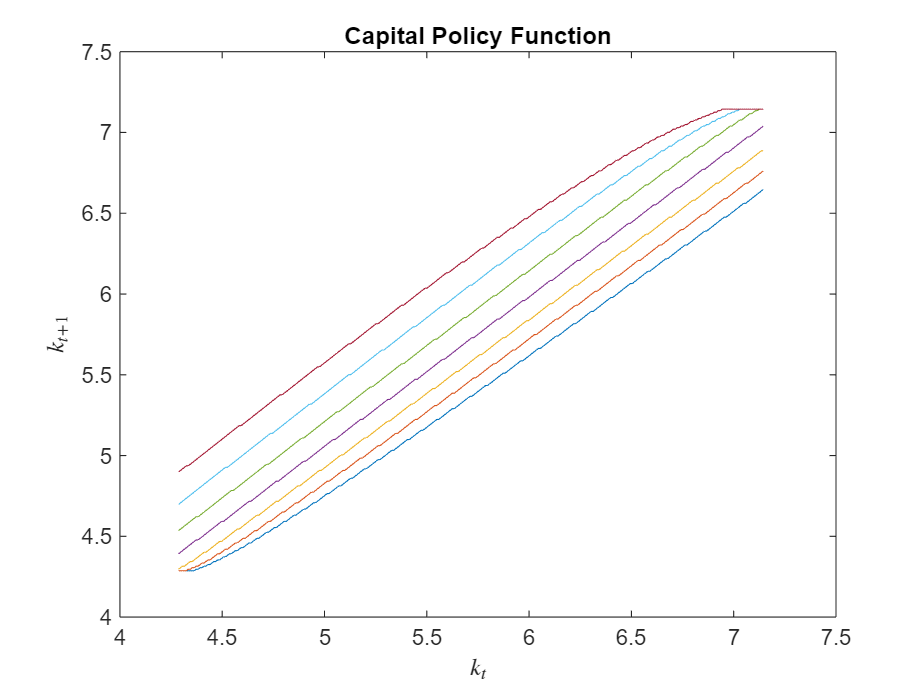

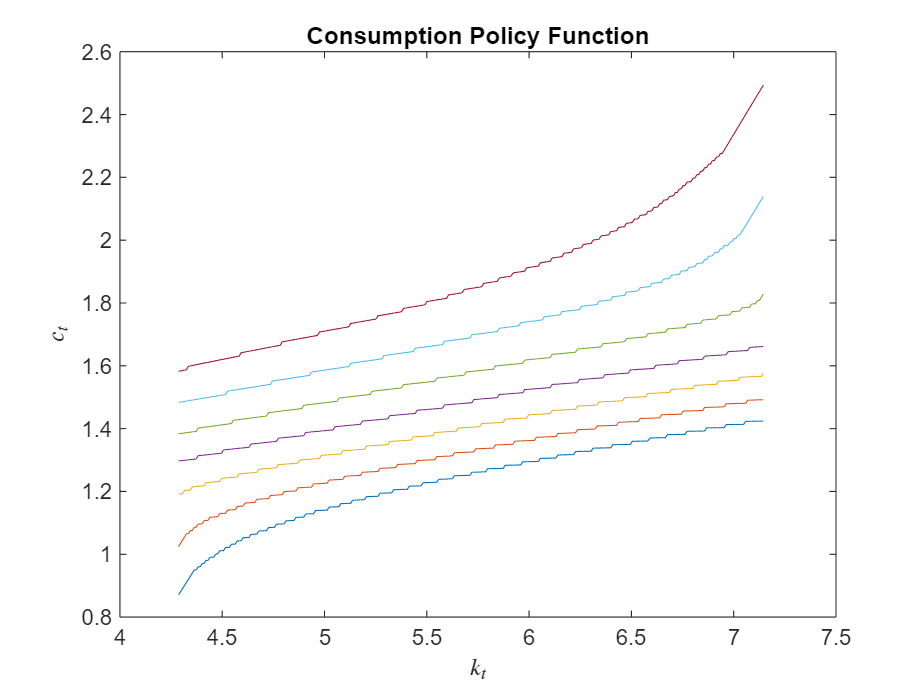

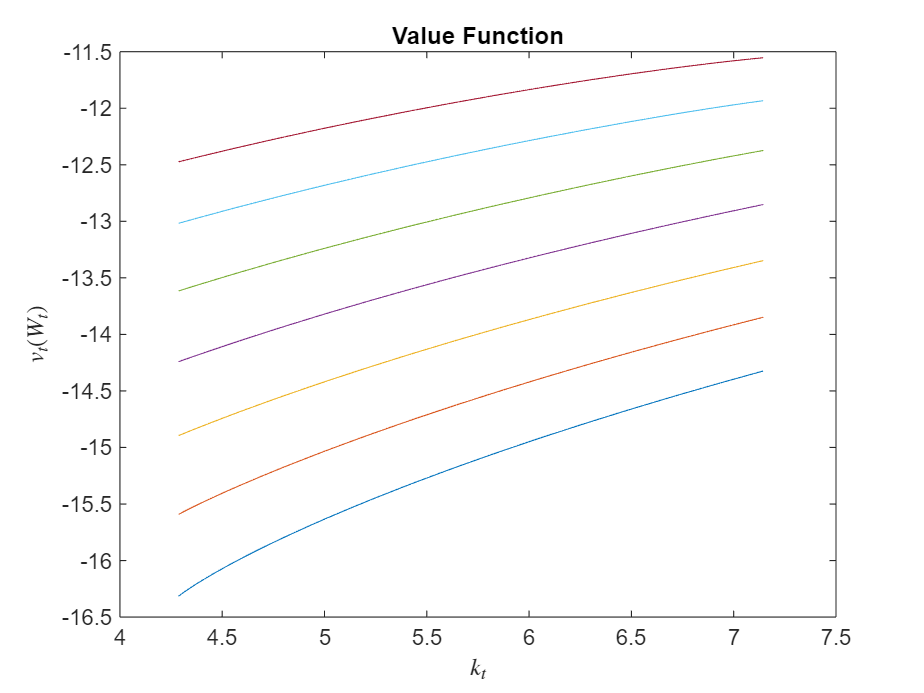

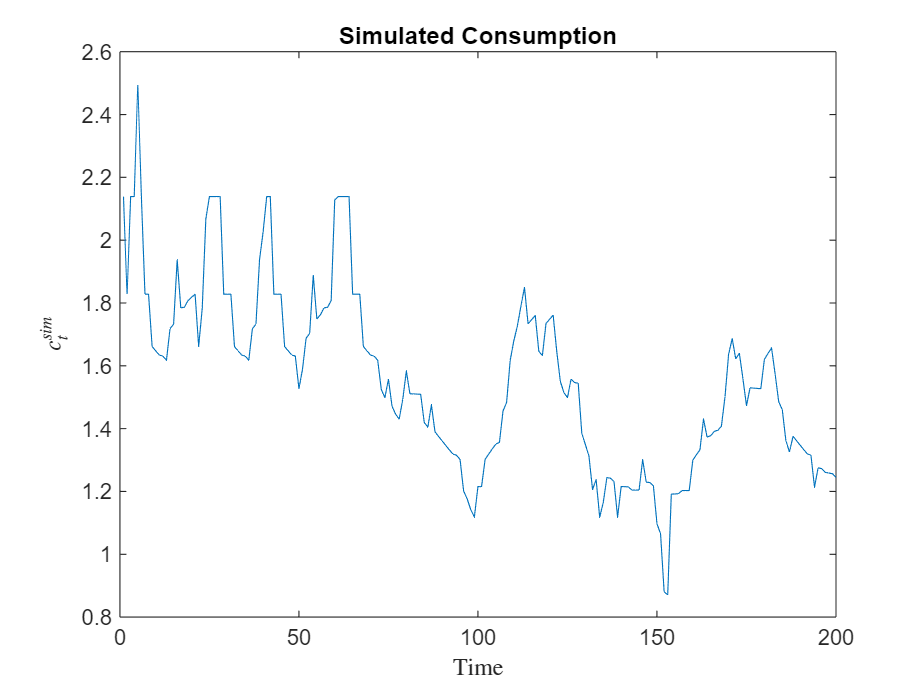

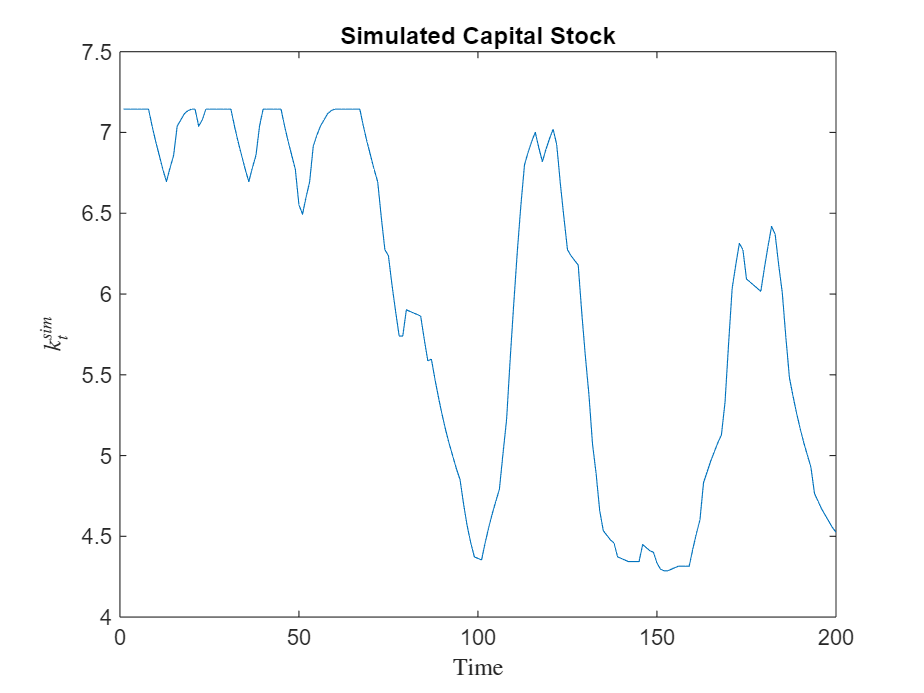

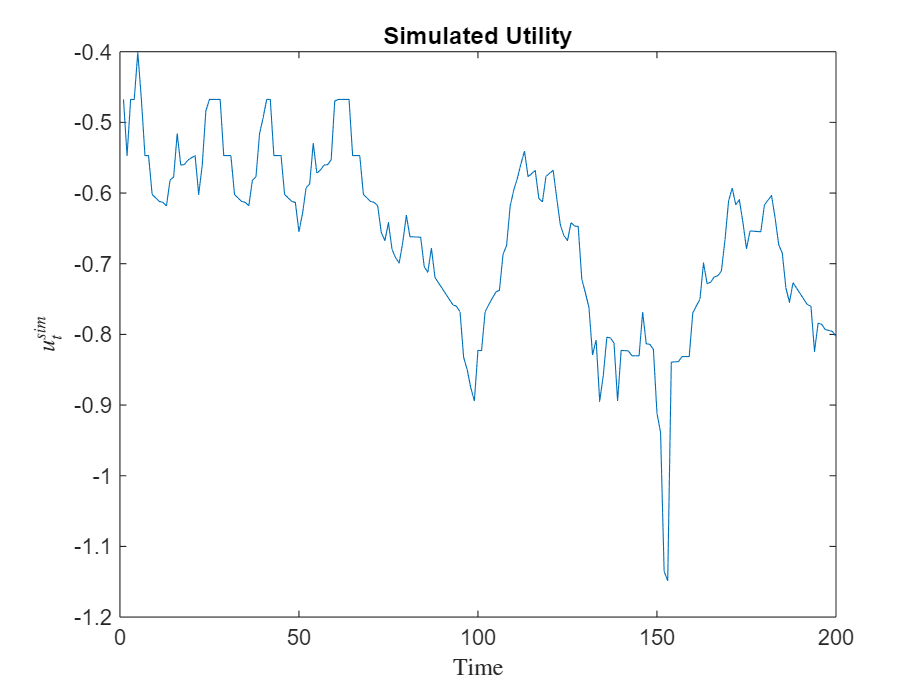

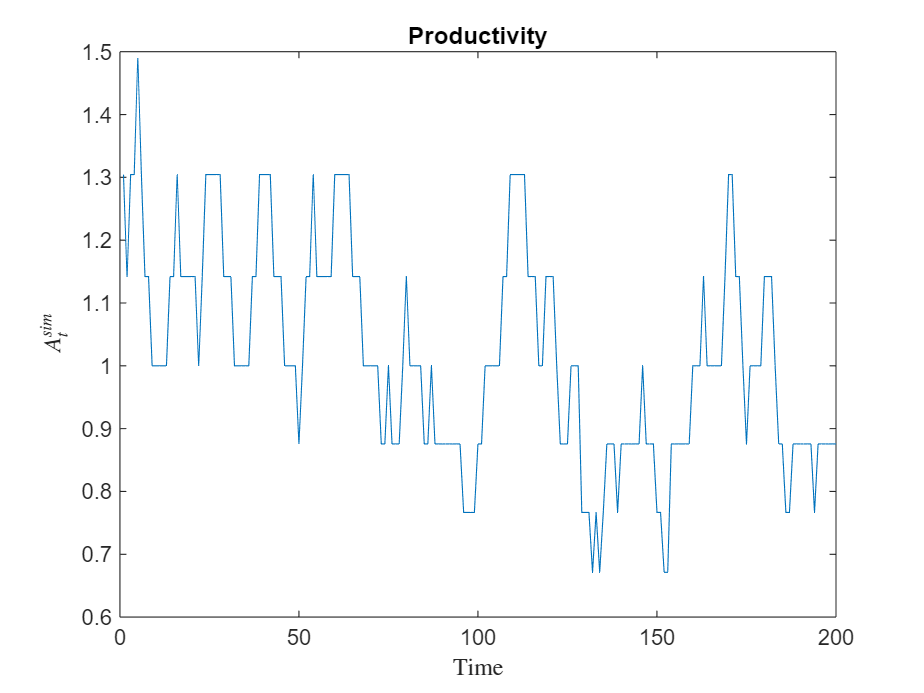

my_graph.plot_policy(par,sol,sim,figout)